clc
close all; 
clear;


## Power Profile Analysis

### Load power profiles 

Get the directory of the power profiles from H24

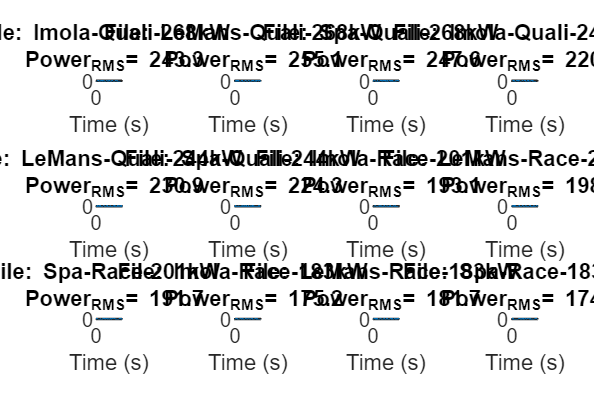

% InputPar.PowerProfile.Folder= "\\wae-fs01\Department\WAE\Business Development\!Proposals\M1444B1 - Mission H24\Technical\240610_Drive Cycle";
InputPar.PowerProfile.Folder="InputDriveCycleProfiles";
InputPar.PowerProfile.Name = "P006-1040-019-A-------Battery_Load_WAE.xlsx";
InputPar.PowerProfile.Dir= fullfile(InputPar.PowerProfile.Folder,InputPar.PowerProfile.Name );

sheetName = sheetnames(InputPar.PowerProfile.Dir);
% read the table for each sheet
fig1= figure('Color','White','Position',[680,7,1500,1000]);
for isheet = 1: length(sheetName)
    data= readtable(InputPar.PowerProfile.Dir,Sheet=sheetName(isheet));
    data.Properties.VariableNames=["sRun_m","Time_Seconds","vCar_kph","Power_kW","Power_RMS_kW"];

    data.Power_kW = -data.Power_kW;
    PowerProfile.(sheetName(isheet))= data;
    
    nexttile()
    plot(data.Time_Seconds, data.Power_kW);
    grid on 
    xlabel('Time (s)'); ylabel('Power (kW)');
    titleName= strrep(sheetName(isheet), "_","-");
    title(sprintf("File: %s \n Power_{RMS}= %.1f", titleName, rms(data.Power_kW)));

end
FigNameMat= "02_SimOutput\H24\PowerProfile.fig";
FigNamePng= "02_SimOutput\H24\PowerProfile.png";
saveas(fig1, FigNameMat)
saveas(fig1, FigNamePng)

## Simulation conditions:

- Continous laps: Spa_Race_183kW and Spa_Race_201kW --> see if the laps are charge neutral and reach the thermal equilibria

- Single lap: Qualification lap (244kW) for Imola, Leman to see when the cells reach the max temperature limit

### Racing simulation with multiple laps

disp(sheetName)

    "Imola_Quali_268kW"
    "LeMans_Quali_268kW"
    "Spa_Quali_268kW"
    "Imola_Quali_244kW"
    "LeMans_Quali_244kW"
    "Spa_Quali_244kW"
    "Imola_Race_201kW"
    "LeMans_Race_201kW"
    "Spa_Race_201kW"
    "Imola_Race_183kW"
    "LeMans_Race_183kW"
    "Spa_Race_183kW"



% these following factors are fixed
InputPar.timeStep=  0.001; % unit: s
InputProfile= {'Spa_Race_183kW'};

    % "Imola_Quali_268kW"
    % "LeMans_Quali_268kW"
    % "Spa_Quali_268kW"
    % "Imola_Quali_244kW"
    % "LeMans_Quali_244kW"
    % "Spa_Quali_244kW"
    % "Imola_Race_201kW"
    % "LeMans_Race_201kW"
    % "Spa_Race_201kW"
    % "Imola_Race_183kW"
    % "LeMans_Race_183kW"
    % "Spa_Race_183kW"
OutputfolerName= string(InputProfile);

InputPar.Racelaps_RestBetweenLaps_s=0; %[s]
InputPar.Racelaps=1;

InputPar.ThermalStableLaps=10; % use the last xx laps to get the RMS power and rejection calculation which reach to thermal stability

% SOH parameter setting
Alpha = 1;  % 0-1  this is the SOH of DCIR
SOHQ  = flip(1);  % 0-1

### Load Bus

load(['Data\BusObjects.mat'])

### Create different simulation cases

% Pack Configuration
Ns_option =[216];
Np_option = [2];

CoolantInTemp_degC= [45, 55];
CoolantFlowRate= [20];
PowerFudgeFactor = [1];

% Generate all combinations of the inputs
combinations = combvec(Ns_option, Np_option, CoolantInTemp_degC, CoolantFlowRate, PowerFudgeFactor)';

% Convert to table
SimCaseTable = array2table(combinations, 'VariableNames', ...
                                          {'Ns', 'Np', 'CoolantInTemp_degC', 'CoolantFlowRate', 'PowerFudgeFactor'});


% load the existing simulation cases from 
existingSimDir= fullfile(pwd, "02_SimOutput",InputProfile,strcat(InputProfile,"_SimulationResult.xlsx"));

if  exist(existingSimDir, 'file') == 2
     disp('Existed simulation results')
     existSimTable= readtable(existingSimDir);
     % check if the simulation scenario already existed 
     % Define the key columns
    keyColumns = {'Ns', 'Np', 'CoolantInTemp_degC', 'CoolantFlowRate', 'PowerFudgeFactor'};
    % Extract the key values as strings for comparison
    simCaseKeys = string(SimCaseTable{:, keyColumns});
    existSimKeys = string(existSimTable{:, keyColumns});
    % Find the indices of rows in SimCaseTable that are not in existSimTable
    [~, idxNotInExistSimTable] = setdiff(simCaseKeys, existSimKeys, 'rows');
    
    % only use the new case for simulation 
    SimCaseTable=SimCaseTable(idxNotInExistSimTable,:);

    SimCaseTable.SimNo= [max(existSimTable.SimNo)+1:max(existSimTable.SimNo)+length(idxNotInExistSimTable)]';


else % if not exist the file then just create case number 
    
    SimCaseTable.SimNo= [1:size(SimCaseTable,1)]';

end

% Reorder columns to place 'SimNo' as the first column
SimCaseTable = SimCaseTable(:, {'SimNo', 'Ns', 'Np', 'CoolantInTemp_degC', 'CoolantFlowRate', 'PowerFudgeFactor'});

### Thermal parameters

[CellPar, stopState] = MissionHelper.createCellPar;
CellPar.InitialCon.TempAmbient         = 50;      % unit: [°C] set based on Fred email that the inlet temperature is 50degC
CellPar.InitialCon.TempCellStart       = 45; % assumption by YL, the temperature variance is 6degC


## Loop over different simulation case for different power profiles

ans = logical
   1


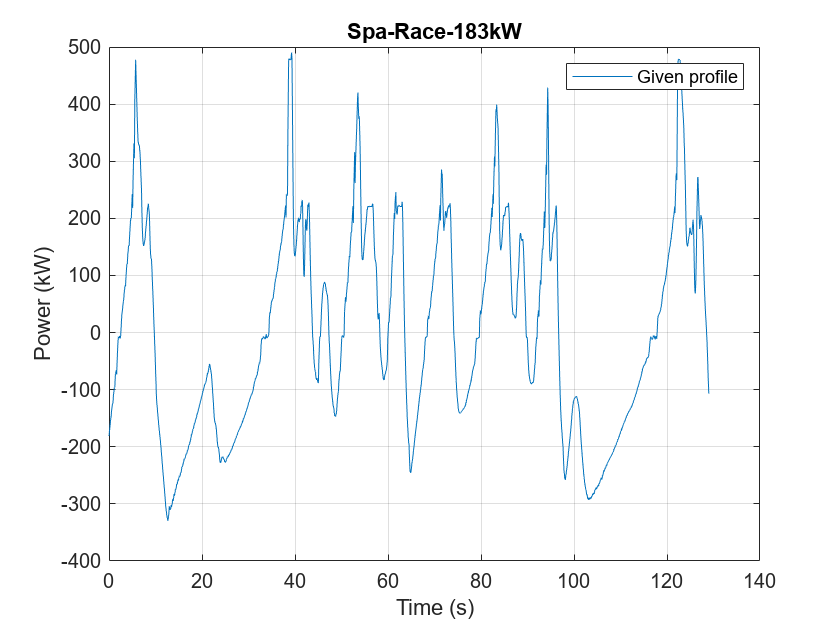

fig =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [1 1 1]
    Position: [1000 818 560 420]
       Units: 'pixels'

  Show all properties


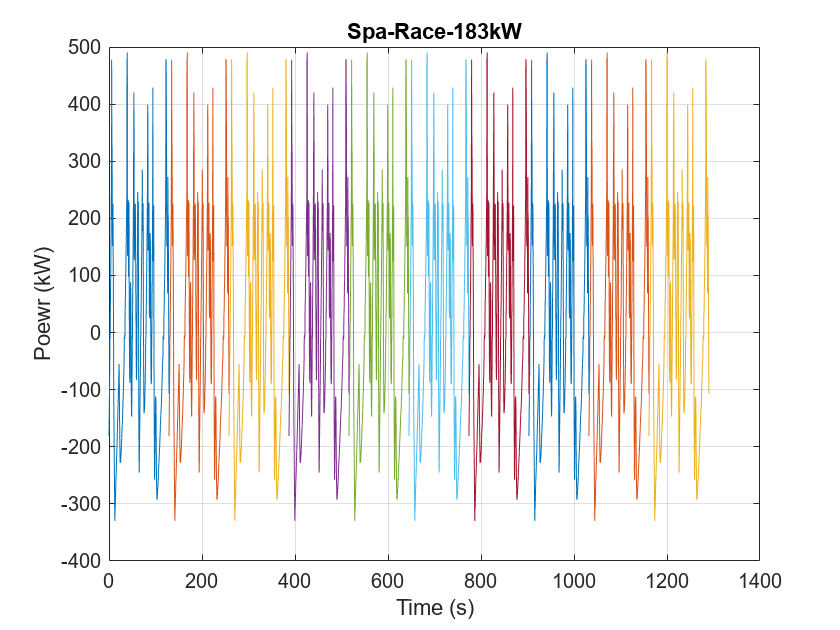

ans = logical
   1


fig =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [1 1 1]
    Position: [1000 818 560 420]
       Units: 'pixels'

  Show all properties


SimResultsTable=[];
for iCase =1:length(SimCaseTable.SimNo)

    Ns = SimCaseTable.Ns(iCase);
    Np =SimCaseTable.Np(iCase);
    CellPar.ThermalProperties.CoolTIn       = SimCaseTable.CoolantInTemp_degC(iCase);     % unit: [°C] set based on Fred email
    CellPar.ThermalProperties.CoolFlowRate  = SimCaseTable.CoolantFlowRate(iCase);
    InputPar.Racelaps_PowerFudgeFactor      = SimCaseTable.PowerFudgeFactor(iCase);
    InputPar.ProfileName= strrep(InputProfile{:}, '_','-');

    InputPar.cutTime= 129; 

    [TimeEnd, dTime,PowerInput, SOCstart,TimeThermalStable_Start]=MissionHelper.compileInputH24_NewProfiles(PowerProfile,InputProfile,InputPar);

    % Pass the values to InputPar
    InputPar.CoolFlowRate  = CellPar.ThermalProperties.CoolFlowRate;
    InputPar.CoolTIn       = CellPar.ThermalProperties.CoolTIn;
    InputPar.Ns= Ns;
    InputPar.Np= Np;
    InputPar.ThermalRes_CellCool_hotcell = CellPar.ThermalProperties.ThermalRes_CellCool_hotcell;
    InputPar.ThermalRes_CellCool_coldcell = CellPar.ThermalProperties.ThermalRes_CellCool_coldcell;
    InputPar.TimeThermalStable_Start=TimeThermalStable_Start;
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    out = sim('03_myModels\H24_outletEstModel_2cells.slx');
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    [SimResults,resultSummaryPre]= MissionHelper.getSimout(out, InputPar);

    SimResults_Pre= [SimCaseTable(iCase,:), resultSummaryPre];

    SimResultsTable=[SimResultsTable; SimResults_Pre];

create figures

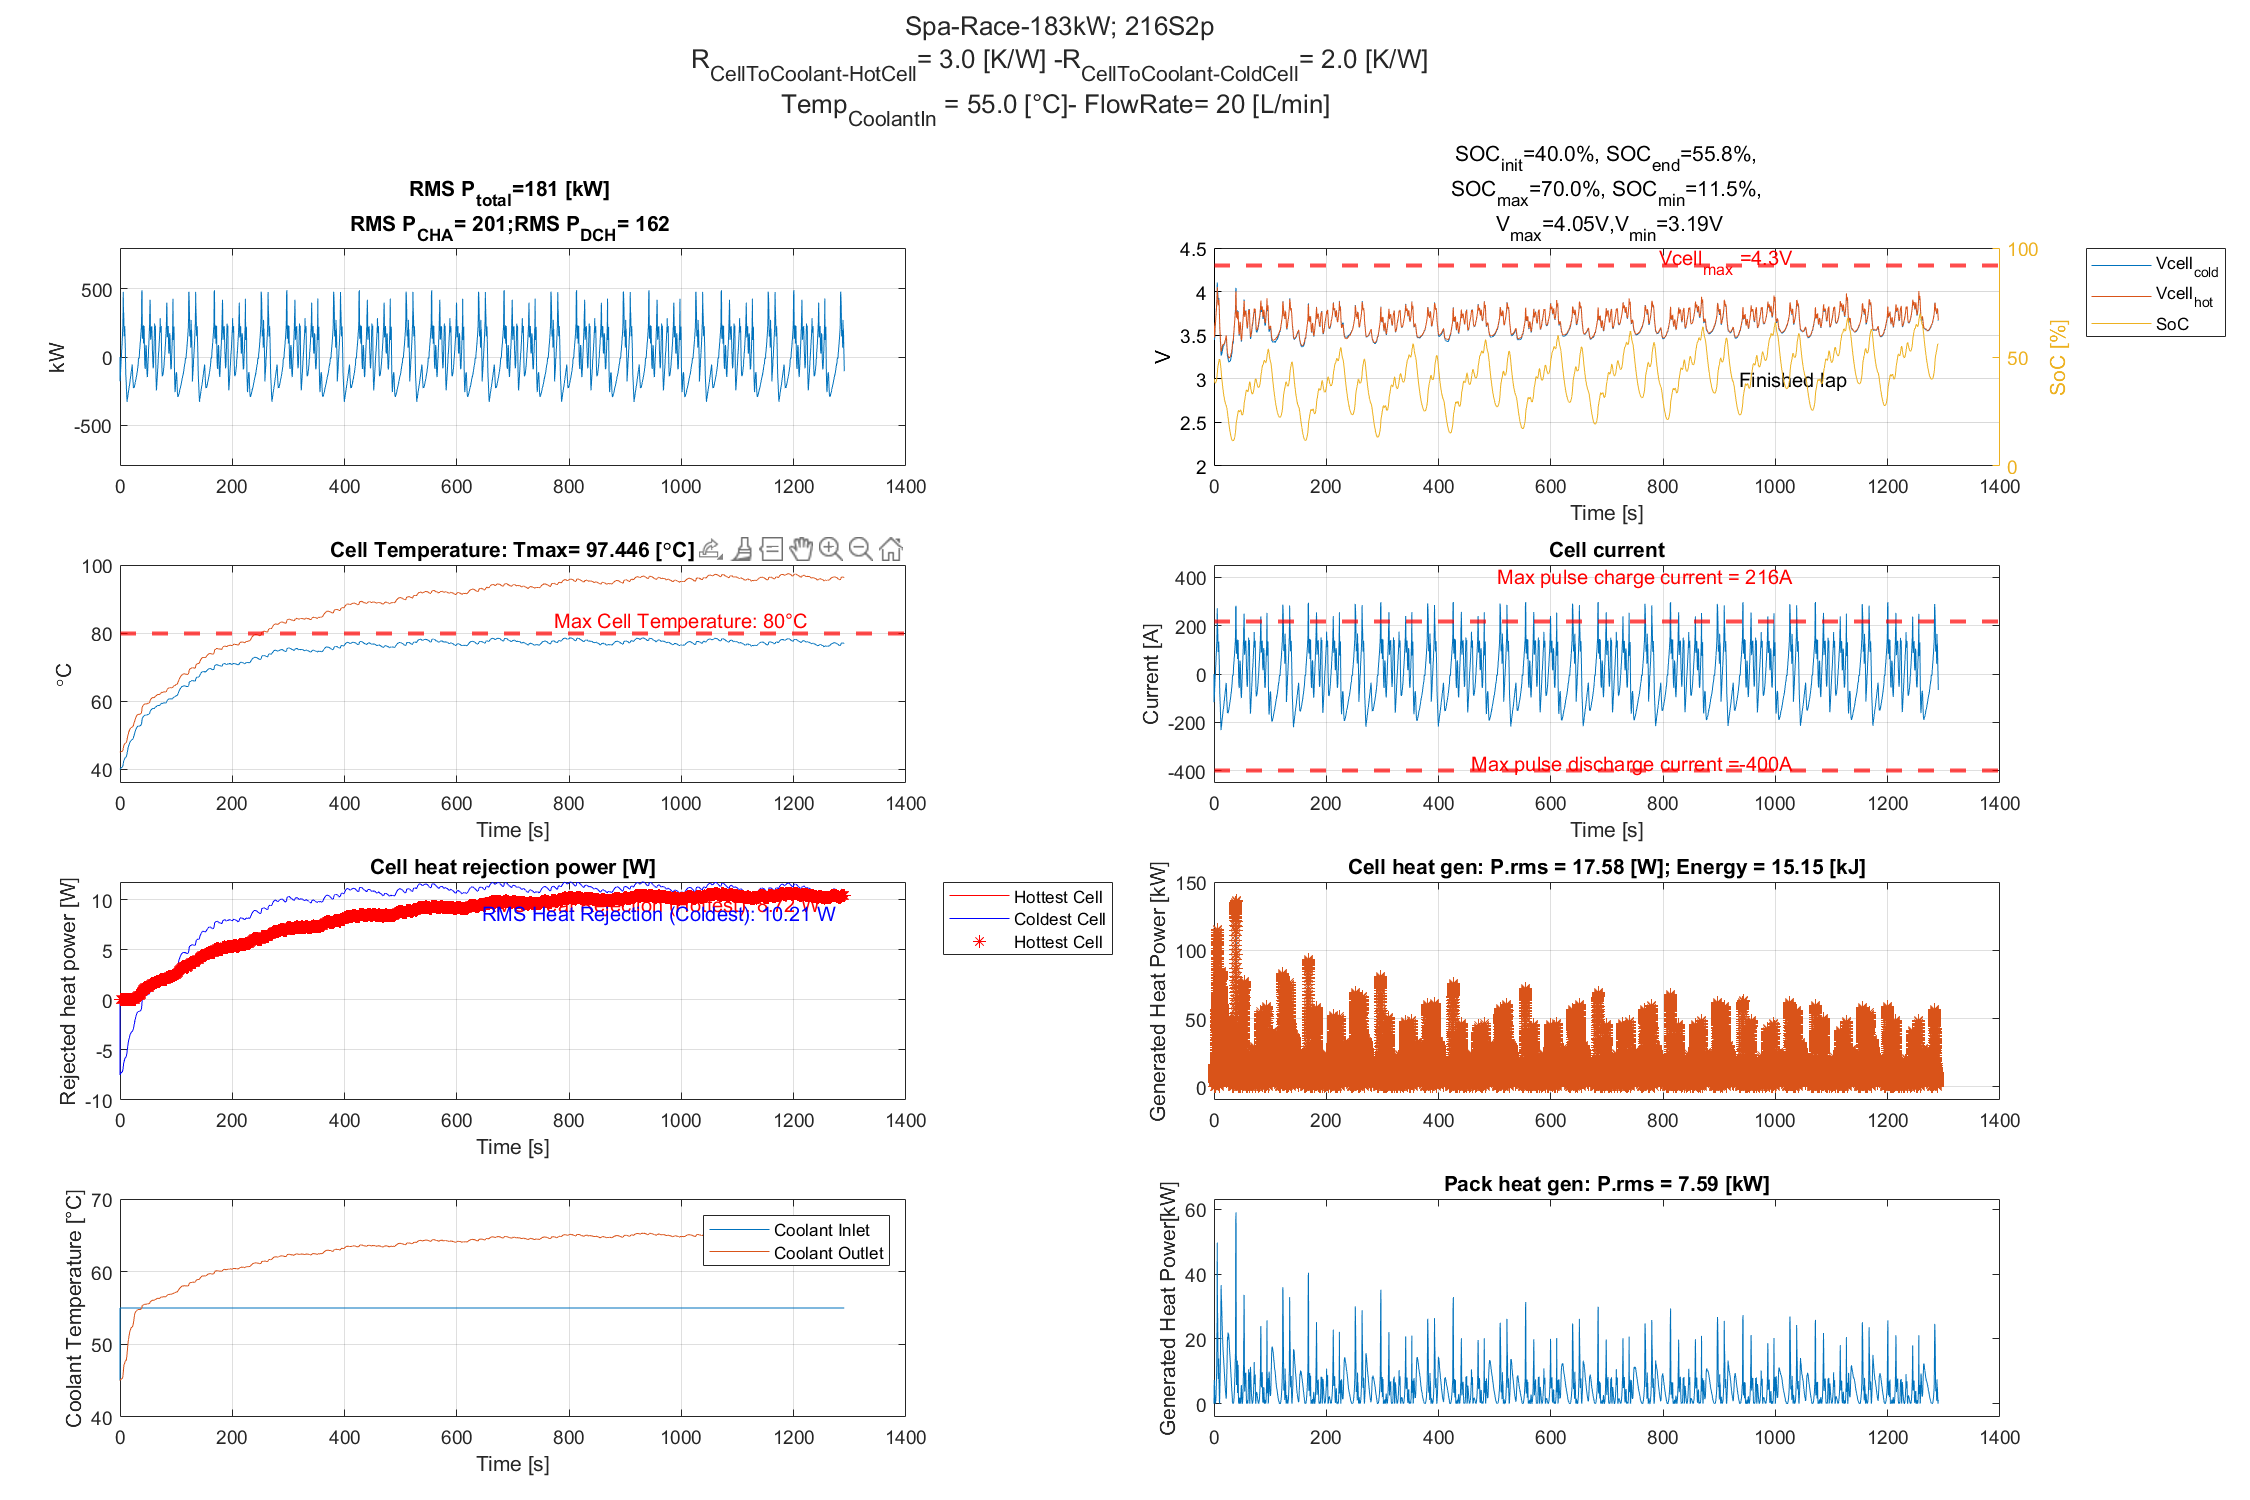

    close all;
    fig=figure('Color','White','Name',['Alpha=',num2str(Alpha),'- SOHQ',num2str(SOHQ)],'Position',[680,7,1500,1000]);
    tiledlayout(4,2,"TileSpacing","compact","Padding","compact");

    fig=PlotHelper.PlotSimoutNew(fig, SimResults,InputPar,...
                                SOCstart);
    set(fig, 'Visible', 'on');


    % save figures to the path
    figName= sprintf([ 'SimCase%d_','CoolInTemp%.1d', ...
        'PowerFudge%.2f.png'], ...
        (SimCaseTable.SimNo(iCase)),...
        round(InputPar.CoolTIn,1), ...
        InputPar.Racelaps_PowerFudgeFactor);
    figNameMat= strrep(figName,'.png','.fig');

    subfolderDir= fullfile("02_SimOutput",OutputfolerName,strcat(num2str(Ns), 's',num2str(Np),'p'));

    if ~exist(subfolderDir, "dir")
        mkdir(subfolderDir)
    end

    saveFigDir= fullfile(subfolderDir, figName);
    saveFigDir_mat= fullfile(subfolderDir, figNameMat);

    saveas(fig,saveFigDir)
    saveas(fig,saveFigDir_mat)
    

end

## Save the simulation result to excel

% resultDir= fullfile("02_SimOutput",OutputfolerName,strcat(InputProfile,"_SimulationResult.xlsx"));
% 
% % if there is already simulation cases, add it to the original one. 
% if  exist(existingSimDir, 'file') == 2
%     SimResultsTable=[existSimTable; SimResultsTable];
% end
% 
% writetable(SimResultsTable, resultDir)

%{
% AlphaVct = [1];  % 0-1
% SOHQVct  = flip([1]);  % 0-1
% set_param(gcs,'SimulationCommand','Update')
resultTable=[];
for idxCoolR = 1:length(CellPar.ThermalProperties.CoolTIn)

    for idxCoolFlowRate = 1:length(CellPar.ThermalProperties.CoolFlowRate)

        
        InputPar.CoolFlowRate  = (CellPar.ThermalProperties.CoolFlowRate(idxCoolFlowRate));
        InputPar.CoolTIn = CellPar.ThermalProperties.CoolTIn;  
        
        InputPar.Ns= Ns; 
        InputPar.Np= Np;
        InputPar.ThermalRes_CellCool_hotcell = CellPar.ThermalProperties.ThermalRes_CellCool_hotcell;
        InputPar.ThermalRes_CellCool_coldcell = CellPar.ThermalProperties.ThermalRes_CellCool_coldcell;
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        out = sim('H24_outletEstModel_2cells.slx');
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Save Output

        [SimResults,resultSummaryPre]= MissionHelper.getSimout(out, InputPar);
        
        resultTable=[resultTable;resultSummaryPre];

close all; clc

        fig=figure('Color','White','Name',['Alpha=',num2str(Alpha),'- SOHQ',num2str(SOHQ)],'Position',[680,7,1500,1000]);
        tiledlayout(4,2,"TileSpacing","compact","Padding","compact");

        fig=PlotHelper.PlotSimout(fig, SimResults,InputPar,...
                                   SOCstart);

        % save figures to the path
        figName= sprintf([ 'CoolInTemp%.1d', ...
                            'PowerFudgeFactor%.2d.png'], ...
                            round(InputPar.CoolTIn,1), ...
                            InputPar.Racelaps_PowerFudgeFactor);
        figNameMat= sprintf([ 'CoolInTemp%.1d', ...
                            'PowerFudgeFactor%.2d.fig'], ...
                            round(InputPar.CoolTIn,1), ...
                            InputPar.Racelaps_PowerFudgeFactor);

        subfolderDir= fullfile("02_SimOutput",OutputfolerName,strcat(num2str(Ns), 's',num2str(Np),'p'));
        
        if ~exist(subfolderDir, "dir")
            mkdir(subfolderDir)
        end

        saveFigDir= fullfile(subfolderDir, figName);
        saveFigDir_mat= fullfile(subfolderDir, figNameMat);
        
        saveas(fig,saveFigDir)
        saveas(fig,saveFigDir_mat)

    end
end

  % resultTable.Properties.VariableNames= {'CoolTempInlet_degC', ...
  %                                   'CoolFlowRate_LperMin', ...
  %                                   'CoolTempOutlet_degC', ...
  %                                   'ThermalResistance_CellToCoolant', ...
  %                                   'PackPower_RMS_kW', ...
  %                                   'PackHeatGeneration_RMS_kW', ...
  %                                   'PackHeatGeneration_Max_kW', ...
  %                                   'TotalHeatGeneration_Pack_kJ', ...
  %                                   'MaxCellTemperature_degC', ...
  %                                   'HottestCellHeatRejection_RMS_W', ...
  %                                   'ColdestCellHeatRejection_RMS_W', ...
  %                                   'HeatRejection_HottestCell_kJ', ...
  %                                   'HeatRejection_ColdestCell_kJ', ...
  %                                   'UnfinishedLap'};
  % 
  % 
%}